## Q1 - part c | Good Approach

clear; clc;

%%

load q1_402123100.mat

y_tilda = y-v;

u_val = u(length(u)/2+1:end);
v_val = v(length(u)/2+1:end);
z_val = z(length(u)/2+1:end);
y_val = y(length(u)/2+1:end);
y_tilda_val = y_tilda(length(u)/2+1:end);

u = u(1:length(u)/2);
v = v(1:length(v)/2);
z = z(1:length(z)/2);
y = y(1:length(y)/2);
y_tilda = y_tilda(1:length(y_tilda)/2);


Ts = 0.1; 
t = 0:Ts:length(u)*Ts-Ts;
N = length(y);
data = iddata(y,u,Ts);



fprintf("===============Degree Extraction | Best Fit Lowest Error Method====================\n")

===============Degree Extraction | Best Fit Lowest Error Method====================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 1;

for degree=1:1:100
    na = degree;
    nb = degree;
    p = na+nb;

    U = arx_U_builder_3(u,y_tilda,na,nb,1);
    theta_hat = inv(U'*U)*U'*y_tilda;
%     theta_hat = U'*y\(U'*U);

%     [theta_hat, arx_U, detUtU, rankU] = UCalc(na, u, y_tilda);
    
    y_hat = form_tf_lsim_2(theta_hat, u, t, na, Ts);
%     y_hat = arx_U*theta_hat;

    [r2_arx, mse_arx] = rSQR(y_tilda, y_hat);

    error = y_tilda - y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    
    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f |\n", degree, r2_arx, mse_arx, variance)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
%     dets = [dets; detUTU];
    vars = [vars; variance];
    

end

>>> Degree = 1 : R2=-0.027254 | MSE=3.402397 | var=3.416062 |


-------------------------------------------------------------


>>> Degree = 2 : R2=0.341361 | MSE=2.181497 | var=2.199090 |


-------------------------------------------------------------


>>> Degree = 3 : R2=1.000000 | MSE=0.000000 | var=0.000000 |


-------------------------------------------------------------


>>> Degree = 4 : R2=-13451075218161955013999236922194319069275330080424780452296474314687859099241566699520.000000 | MSE=44551677026421316065655920546586414947762096340898444956834062870355783831069787160576.000000 | var=45276094539046058130645531055656374795955749872972948760629205452361159422751839092736.000000 |


-------------------------------------------------------------


>>> Degree = 5 : R2=-1842135211370272755529570028143039017524135827887064161237742992019902323628898075223204850832836272855755191778102915278051550833911952681126484767590196918497757803421939279793942961099833096536064.000000 | MSE=6101386814427567117715167015337240402901433136446865712987095980301083975398550779201682465175751048227420788494405736742687134013006568317609825373357033565567189992632060912115852032593931104419840.000000 | var=6225904912681190611257521760486715499131131841801723791052270759267275567073538631591374029249393270132570846282484015723560655372557101132308390593604785632505308910897601781446009725875509883043840.000000 |


-------------------------------------------------------------


>>> Degree = 6 : R2=-754554757341868160245711807654832903877880662776706123497239444473221426425364480.000000 | MSE=2499181612073255651491177045532339226538639824688307694736760066533089602881716224.000000 | var=2560636897616040681773637684255756983476096310171689592224435360260486234722271232.000000 |


-------------------------------------------------------------


>>> Degree = 7 : R2=-403402159755379674138694869606165652464983255713469297370010956107674975409923592936331096186346263523092728048469076243069186547049126159201167467090943551293277274568575544073848433091566779629379353499684130819539617573830248092682476256190619326746684256048660873216.000000 | MSE=1336119413629919219512412547404531156284935062946836450870730819595892832692765743373715314142645945396219530296596474535369139543169794909710088005090160914540305678439686302820729822149521063373596807897439686033520410782921282993942254822190370947729652368103373275136.000000 | var=1374608450236542307462071375045283637249258984840693787532742852516496705725114287350652207222261013964314016023487598878843768045356958526474223946963764320330757721657312106285232195258899568070480250076844138285782817736548324338414752697403215573248712520466618646528.000000 |


-------------------------------------------------------------


>>> Degree = 8 : R2=-1343128425006663787773012594597420627606063506124569858761608578147472549261357784608741559996776448.000000 | MSE=4448612681542909809578479870838273042521895800544663721523071770212615747832953932002239348138311680.000000 | var=4595674257792262175895096243935458875504496816800038059725402584284030467780170470181185873632034816.000000 |


-------------------------------------------------------------


>>> Degree = 9 : R2=-5595896974846735294589520927661681016832.000000 | MSE=18534324628553133381902059229390357659648.000000 | var=19226477830449311437028617181533378183168.000000 |


-------------------------------------------------------------


>>> Degree = 10 : R2=-1159715909422808433885927497364536547082240.000000 | MSE=3841127032673570700463687500730931620085760.000000 | var=4001173992368303509324279911287791735013376.000000 |


-------------------------------------------------------------


>>> Degree = 11 : R2=-1654258410874384112694689642652351635732143461202265709489470264688370824190565339453877150903646511273726995677534714354287315616855670294717661184.000000 | MSE=5479114884437274186271279617447698557189711509173871804379489633674051460017197333174551505399185874679352763644611833944482696268161089580090523648.000000 | var=5731291720122671864727033530769863621056331188532529298592953772230475472776790842781184615387627648943136223348125398311041105932770553606424231936.000000 |


-------------------------------------------------------------


>>> Degree = 12 : R2=NaN | MSE=NaN | var=NaN |


-------------------------------------------------------------


>>> Degree = 13 : R2=-16936951939201861542903502045407463345150579258959778414574992455056659016751425059922005622483375672149967017956838382319340373586198949734265115153297200748809129148562237912880794816907889084582508576672254617110708224.000000 | MSE=56097345406893869859850875198554104874045170012763314025205928216244796212948118817764516871042196865117430834516096730219392950171911807219691000125561323948030625660104527417328920817370486313436140211775768468838678528.000000 | var=59174414986174970238576134052733827595918896044631258182510359548190339689142244692944668810728711228516861442098653684837395856040337112851944346184711691962225058171811497487055078526909140858666803450808657503487787008.000000 |


-------------------------------------------------------------


>>> Degree = 14 : R2=-223011169080376312826374830253267570556364164050800217019064838668683066285233624315854848.000000 | MSE=738641440703445622901049068903897963581334889215318565861829103294788019294243252269481984.000000 | var=782459153287548353301579976766120108313075104581224119124600617905413859375850242388787200.000000 |


-------------------------------------------------------------


>>> Degree = 15 : R2=-693490923620372471995195692619183347318662965006509900884232156217344.000000 | MSE=2296930405100456158433010463219169797685563379296271519490972789506048.000000 | var=2443542984149421436989928466903963304142370471856091065316252317646848.000000 |


-------------------------------------------------------------


>>> Degree = 16 : R2=-246441602129990861505993351890244907762029192469509393467089879040.000000 | MSE=816246023897372328152723173293639806222024881328679688928067846144.000000 | var=872057717839073112886163862698913757673547355536948123855929475072.000000 |


-------------------------------------------------------------


>>> Degree = 17 : R2=-85203982754363489788421333731084485831474468468625733874773716884258433197314015440222057135090393957315742537876917139284164608.000000 | MSE=282206460039101775076256593982194533478782425114510822565581941444754425464926801435507755464476189759525032160098197431937662976.000000 | var=302796630943242273368053590666039092934970477851023071012728107654640221730227524063384934153183420803025296259984187344071688192.000000 |


-------------------------------------------------------------


>>> Degree = 18 : R2=-1372238781849414953869355197793143858684294624787800802239175651753984.000000 | MSE=4545029896906554747172879403455202986556176403369492507137821726736384.000000 | var=4897661526838959810628237348286977319528512546509520868333110243098624.000000 |


-------------------------------------------------------------


>>> Degree = 19 : R2=-70811752042293966767197276642727744691402549509832618438599067503090104590123872345558540791495122054358761472.000000 | MSE=234537555957136450661033610722324659331905044158950606030786396294516349738480057278268769090304140329474850816.000000 | var=253828523763134672992544799996606239136119921148958786162942924409739967593322954918777504768897013194483040256.000000 |


-------------------------------------------------------------


>>> Degree = 20 : R2=-20167906667867589366957499332882200168674685710353796230826488684461940118884232236349728232338295274980278639001600.000000 | MSE=66798679629168309780277088436672199304151071942524447696847875804402474742940211722215488493988996908611706697023488.000000 | var=72607260466487295521780200248221355110601315190696693952054923328137406208347819430185182310206394786069952868646912.000000 |


-------------------------------------------------------------


>>> Degree = 21 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------


>>> Degree = 22 : R2=-1821737214880425489785368259118442541726345076051913317962040534780318399137830502838645790780360185776088704430295700757632233210415413179002109012705790614860622639136768.000000 | MSE=6033826047956294494660098463847347149871016108712644656371144621907940000505957310150043779134384551722424597512691917515056670973531607245741582221635794451814972833923072.000000 | var=6616037333285410705381661255650706468958359758252825470466554411558107559704596383777933786305860825600900223823725293078969062377565995194036691029388412913986026036264960.000000 |


-------------------------------------------------------------


>>> Degree = 23 : R2=-164635026186188171476397651293284305554968546635823318952395417978367115264.000000 | MSE=545292208609457389507497228853220176859785055651704420287300582202274742272.000000 | var=600542079966362690329921136679651698092905532481780193409555440766929600512.000000 |


-------------------------------------------------------------


>>> Degree = 24 : R2=-296433846704485806733123631500717216443192207406114566958584976089561286704063125395603456.000000 | MSE=981826715253665833557373773384962625832849233550835114270148311670672134233648470519971840.000000 | var=1086091499174409120926446721847222039313359954088164552674647266896893716251171843278372864.000000 |


-------------------------------------------------------------


>>> Degree = 25 : R2=-235738605454228907463688123791815110167682392809937870008855357649212205422112419467003185636491709880191373240256180818560685667794367640418754401170757903625623458065416192.000000 | MSE=780796333565585900621319819726223642931395651956195247818199577288305488977735003321209646551543608684867213217347062089547486226822462487433294043639945013811194073926598656.000000 | var=867551481739539975007837347987836056365205112964221423595416598770362304661917495776992556228101547175039098472931197594740193123786747225777288489407061905155901038239154176.000000 |


-------------------------------------------------------------


>>> Degree = 26 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------


>>> Degree = 27 : R2=-13832553023595266750862429030289520326665568256.000000 | MSE=45815180181727829841906902337253169119495192576.000000 | var=51362309620771113280860560217732170519238672384.000000 |


-------------------------------------------------------------


>>> Degree = 28 : R2=-607099993266250179330128919335877278970872332288.000000 | MSE=2010792623196442252438367022866280217998142734336.000000 | var=2264406107203200673332488748029943827058481168384.000000 |


-------------------------------------------------------------


>>> Degree = 29 : R2=-240337675257316016175508588622099860962301972814123648724235839611323796467028763045059272150425714195010546061803520.000000 | MSE=796029039439719206009076613124543903339665774140825794052394611508936002037679379484881695456855940911301195689099264.000000 | var=900485338732713838856031069495044898661323722138706310730420050272535989523211091937678297041247903375264947709673472.000000 |


-------------------------------------------------------------


>>> Degree = 30 : R2=-170025418513639908826058844308035602481152.000000 | MSE=563145875630371213036497418982314842521600.000000 | var=639938495034512668232551541477102738997248.000000 |


-------------------------------------------------------------


>>> Degree = 31 : R2=-264510561720458424457344413200333663417719250067668224588033075475364869077803113670424785565195040419966470026428416.000000 | MSE=876092723051283548395085974203355525110301601520446647497099822328639641621905661026785884297058772202693059957227520.000000 | var=1000105848232058772970658684566651343450407734545543139909377312157294840978554290867198086138712403188246432687587328.000000 |


-------------------------------------------------------------


>>> Degree = 32 : R2=-729216794574482335215306515339591049918224453777489920.000000 | MSE=2415259047117566372859853495301501572523150764205408256.000000 | var=2769792485226566882037768031328962300562167929560367104.000000 |


-------------------------------------------------------------


>>> Degree = 33 : R2=-4800206846586628971288630552166400.000000 | MSE=15898897420511690606087367573897216.000000 | var=18316702097363698525533219391012864.000000 |


-------------------------------------------------------------


>>> Degree = 34 : R2=-74621493976252693788753920.000000 | MSE=247155907237082374302859264.000000 | var=286060077820697282833547264.000000 |


-------------------------------------------------------------


>>> Degree = 35 : R2=-645620334813531508057604564406255321484361728.000000 | MSE=2138376908298404594972569042900251637069119488.000000 | var=2486484777091167942067431410733057491276398592.000000 |


-------------------------------------------------------------


>>> Degree = 36 : R2=-52833618.272990 | MSE=174991686.821362 | var=204429540.679161 |


-------------------------------------------------------------


>>> Degree = 37 : R2=-30347306032333054617493592504668518350848.000000 | MSE=100514148872570139442924842607954817449984.000000 | var=117974353136819437192377359694154331848704.000000 |


-------------------------------------------------------------


>>> Degree = 38 : R2=-1928738983497553920.000000 | MSE=6388229555435719680.000000 | var=7533289570089291776.000000 |


-------------------------------------------------------------


>>> Degree = 39 : R2=-471198047735353457797159340557169063886848.000000 | MSE=1560668043090037710994857038467134425923584.000000 | var=1849132752476348550308426314893504488144896.000000 |


-------------------------------------------------------------


>>> Degree = 40 : R2=-745210289120370742311595261054381366110582233971863604131095260162228343011326937556862049955429333117452417645402637649810106475347968.000000 | MSE=2468231541284439375721248349977681733099037176200138804081685907981144073877361570177873575874494898421933576542597501055262034772361216.000000 | var=2938370882481475278211315541902034883361288947660102042795080121873631985941782095764588529700272849751713269208353300095937590799106048.000000 |


-------------------------------------------------------------


>>> Degree = 41 : R2=-145675498986683204426928765460281103110532207109360501765743123899190022144163232469511410279234911097138884373629888649149833185911339091769870799681834105783154291144635307026500415269834737057792.000000 | MSE=482495835928001349375557721452443078000186643395639472175094500457891363294847841907920159433576501792080559427832271484583336778524338534185075549211331273099240342469899906369502862886409424863232.000000 | var=577148129100480070913798873126636606337333395811884632670843616799383758977762220215613064685865896827742842569947181549863727918469879476794339872978341775500431514240119879708981718916194094809088.000000 |


-------------------------------------------------------------


>>> Degree = 42 : R2=-114117522375265636586748620073008019656624529735627252432896.000000 | MSE=377971791656739487971253287666098731225698578698760502640640.000000 | var=454293018818196426201445314074307506874281120637583699738624.000000 |


-------------------------------------------------------------


>>> Degree = 43 : R2=-10159715164529124354031616.000000 | MSE=33650272662172146738397184.000000 | var=40640425920497766201556992.000000 |


-------------------------------------------------------------


>>> Degree = 44 : R2=-15344038537594285334466884570393346048.000000 | MSE=50821413018703993148701351726901362688.000000 | var=61676472110077659387515318331259224064.000000 |


-------------------------------------------------------------


>>> Degree = 45 : R2=-8612962668631258689611634745323564059111714985936488292839406393904242011383162000292918739423829712909641987846458917770640207325220132585184215785148350238784984401000922505582508295405580915299051780068106391488509111089233920.000000 | MSE=28527231082268676788387734804845906172700440712386789957745185652120712472017398165954559698713189723748046851835134411918465597457044145084370188873226916638657976932524118926450133324109641294928729310314818737890237323681988608.000000 | var=34789306197888627339488906101476510670975657416970754155346444014770119922526773755251951534902993307578600325127904667181730670265105332080896090524892985448524090082454491671493361049362979431332568973115091761141890026351624192.000000 |


-------------------------------------------------------------


>>> Degree = 46 : R2=-28306972027400076410704828781703176428455178404614648012266342020859907374289002964813433769315740284106305145854742845468433474417346395092145910038877215696137668721265506404870542521843758187836236321940813013704032995145416704.000000 | MSE=93756302370376539989833343876470147672572410122616604975295811356475588029131832669933857529079815552583870265740651323800778715744665944539874254872378076006452399904892182246723450201235121072701930778544479813310552438585950208.000000 | var=114897429375461455360116673580517994392859920759954747471141343564344452528035848611773685952667363026337466836369435778498783515724964237046063134472285558128959207981138206697751590005952837241001474982963111511425235839732416512.000000 |


-------------------------------------------------------------


>>> Degree = 47 : R2=-8968959714864318903060841506179694511432049782326912279782304199859128662742000288419854996080387735491311492537096701629959719952547293391147949544785153203967355411606968540840208831922810521783580307652303970797685588468312587523558066969350315427032133286836219028474479558729952693059584.000000 | MSE=29706338712617838555250764056329326397556337182054842552860568946925021544767305986471357259281827528783323407928073640529981988977237443847777747215422161973837519069320182913935256341212647875455092589028314292540578832938588725063712858458737791318871058373420000009620523460148245586509824.000000 | var=36584160976130344729311242574536480574512937722287891781443173123413727474337536987604263881624521434067511004581915555180749331947068617241330567135752425008869035733376004349741453353904764204176621639252326083559421401705849842264870592691850219596412110200128713651456579207624617300590592.000000 |


-------------------------------------------------------------


>>> Degree = 48 : R2=-330499250932526196293526201854871253814077472271399068302623522367070813046686878787505839192751704197794456734764367872.000000 | MSE=1094655679654440838860606695233550018167490524682239650958680140054801175933647348739943259124702923438359623939557163008.000000 | var=1354771880760446674999148162018408595939566363861466864909705802009823882927332461404624668317399982319260643587428188160.000000 |


-------------------------------------------------------------


>>> Degree = 49 : R2=-2832110844199433681768954985947749754446881895631369399020406533328730761566164615168.000000 | MSE=9380312397884279322908437508186219567488393681728191040866646708879713428201969549312.000000 | var=11667055221249103755637918362256358944744994718416103700475338705553638309051378958336.000000 |


-------------------------------------------------------------


>>> Degree = 50 : R2=-14451975568952581788377934481986084697834917166352430879138719669027446517842051072.000000 | MSE=47866786669392228894368958501328669684892362527776353567650350023633861661815734272.000000 | var=59833483336740284432964531429745849939427010220993524857241411120756547008294027264.000000 |


-------------------------------------------------------------


>>> Degree = 51 : R2=-16823064179341527096486483008976839516356608.000000 | MSE=55720134617996534208767804771798847923945472.000000 | var=70000169118086104871156547701479017455550464.000000 |


-------------------------------------------------------------


>>> Degree = 52 : R2=-672471249310990638769408717369794270108104725891213516761539474983228807006571893497272006820757504.000000 | MSE=2227310562385747841533694261592495233655676492908707033876023109713615169942825468898703842954182656.000000 | var=2812260811093116187196000437322689088694661516000563693153348866806125157966625208179164244739096576.000000 |


-------------------------------------------------------------


>>> Degree = 53 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------


>>> Degree = 54 : R2=NaN | MSE=NaN | var=NaN |


-------------------------------------------------------------


>>> Degree = 55 : R2=NaN | MSE=NaN | var=NaN |


-------------------------------------------------------------


>>> Degree = 56 : R2=-1979565338292286422586384504139908334071716933074876090991484299169483979541612578184168984898573332549698706468618651136261379929582615673549740172298369725047440960508030319651767398471669420318235543514576722185267707322524560139728386523136.000000 | MSE=6556572926245792601804758664679845041510672673949475600434125374278074285825107327336796582872501421166733404436719948964009450131262144319302248995612044874612456234492624259112689884963499623108557136463519913687435405778350618592255032688640.000000 | var=8449191915265196823742631729087653551386723535690449668586040554438388280396123511856379290409813260601284359727482793600578359427788335018907743604032096184736976718226969599865385807674340697595979536635323796209374225500463468907357035036672.000000 |


-------------------------------------------------------------


>>> Degree = 57 : R2=-55610251866964539733989548409054252113125471724872348409914815454765880020815883647813249836730746648133632.000000 | MSE=184188248177344854799868943842711675957536446595806307303360478075685859861603389343313390742374702437629952.000000 | var=238585813701223899608353577492586867562926363568911439329869469758068003261754870863808401090942459816443904.000000 |


-------------------------------------------------------------


>>> Degree = 58 : R2=-7553453018784619290478996582720365464063064521697234114667906174531286140349431056438797830149292702381046030163804912607403445113815110924559618151127739924739919072722944.000000 | MSE=25017999964252942428824981999378692125946370328445470704402480930877175727030751868397783496807936668895992610075032703281671716580855981602927594413791449049646539449827328.000000 | var=32575520786787684596099487795364790999588403146655887821011317860833146386930025763783382670094994355638368628353379460235971123696215638071896805261710472711640395185913856.000000 |


-------------------------------------------------------------


>>> Degree = 59 : R2=-150776036052847970307557960654961597132151806969978911507721789817584334821045582081613960001962334536328300882384462848446102554820286445091130119098425132353468436236887654400.000000 | MSE=499389465347770143853475626878365845675393772350371774323405700763612139946185141974246320931200695747406321273796996605379564509320516066669347229472264800578626541055935250432.000000 | var=653651132654149347596447589230785140387868848301233378204519356970675116229165915475095631700542820351340146462333690309061524285633641241507390455269434193584533823198161010688.000000 |


-------------------------------------------------------------


>>> Degree = 60 : R2=-197779479408407499290208441991168.000000 | MSE=655070865796642678711244017369088.000000 | var=861935349732424463476488384020480.000000 |


-------------------------------------------------------------


>>> Degree = 61 : R2=-2485050839858057266355567754803841596273267244341556334902781021265244255815535176576809725645581402966546494075048528332665000601610621114674115054904803328.000000 | MSE=8230805390345724297078718352295711180621526754004173148840185541457527851428139499254674694449606577037548802236369910097832935659239246863866650975738527744.000000 | var=10887308717388523629867716404028076679234918523518438285527516503423917382117702366012008069183096527006581900104092886135856774547526736156305421394753093632.000000 |


-------------------------------------------------------------


>>> Degree = 62 : R2=-37963435619468110332790364050476502595713411862586397326659166358242671289696863079816281852150632538166275622608425718273321393896670350541320257706361011739840259860546869527272279083588566921628352512.000000 | MSE=125739741626617510419449401803697660688628439912842801544714851817408287160009768494792019513602729525968144594907480203137513715222175624146518366718339325524689497687743104523131447404903137016060837888.000000 | var=167207103226884955043380840059710437769833720073835591644752015584718697441575962617081410879251560823079169775102686367142380394427253998784754827024595030229850762085882036459370792870938105454228668416.000000 |


-------------------------------------------------------------


>>> Degree = 63 : R2=-40588132695924349019467821764141919045359849421462407762924535882598697134730619690641113435920872243200.000000 | MSE=134433073166729824271943825560312016074243490387091593270378716206324247753935353484755021444899829448704.000000 | var=179723359848569316465742702639231351999454212967419152256683743579624672978102601253115800273984363167744.000000 |


-------------------------------------------------------------


>>> Degree = 64 : R2=-163119424287328891493641867170414592.000000 | MSE=540272341780712040940159919055699968.000000 | var=726172502393430023707517615970713600.000000 |


-------------------------------------------------------------


>>> Degree = 65 : R2=-4695906555826139777753736472259315101075344982228734755589005810441782190008404290287453876505605408667575326390928570908847059648480678046128487319280478694896403391818457798780229244042298643088922144480293842584042655371808567501184729902314752717399775383502352568610193408.000000 | MSE=15553441552310984255138886726886448121548768437431499868740970710613593408725586581014397013304901856403144498899454128577543389996733752487261032711004931813974849679059640879429142393716737028428294438425176948102143544628913407012843611014986672510561863679721261578344988672.000000 | var=21018164259879709197558141035860354737169370349018265474621276540833903840560998365941348313049388343094048981026112417436864777621964614166633332538652437763661951207998384318913934087167858505083193299135695593135947166660405264298729571085583605597382010377772495864156127232.000000 |


-------------------------------------------------------------


>>> Degree = 66 : R2=-332952806016198652999392405637289397734030928684561732608249366489923676059222721838353171943450834394308786776186332982195534033818001788084807743043466279714994228000633915776312387310677801678622192304128.000000 | MSE=1102782167082502725291297531344102000734255998789046710217816089497290973613310647715472013526174591062283030449294609063846692038711120843759330978208454179107050842559759096543430576259290472968973191217152.000000 | var=1498345335709922286484766346360625975046431108279890262775408577069035045461390559786888391404470328346196770169304898506475482051380496094384933752161549116035724562279076490254538098347547043991622906806272.000000 |


-------------------------------------------------------------


>>> Degree = 67 : R2=-3148989362946243394804133206916115464192.000000 | MSE=10429854474993247098068260266615322443776.000000 | var=14248435075127388357895983894116662509568.000000 |


-------------------------------------------------------------


>>> Degree = 68 : R2=-62161987089715039096687662080536785638802891372852127104175098531597284267607103423756225750861431364633860871179466663285806501941055848448.000000 | MSE=205888431015701959185707725863746186592292938670640580053357452148485479500825106431401642153836220938168332591019246332594718941418440622080.000000 | var=282813778867722459321058611714226424923621371069220464090157022703260835691731241399054600571510419386331817606496393463544648989433372082176.000000 |


-------------------------------------------------------------


>>> Degree = 69 : R2=-62346800164559301762541902596243751313045677407142937117507809919189981893315207014333284352.000000 | MSE=206500555495505915631605383867810045560478204165386645814033972956982686581156227389163831296.000000 | var=285221761734124217491142439799038868495041292131663612179021562797830868311635586474842259456.000000 |


-------------------------------------------------------------


>>> Degree = 70 : R2=-6153870362862786643728993441628101717244121983221760.000000 | MSE=20382403668261754368459710441870703517664291632185344.000000 | var=28308893983696880476537155264857811372841711586770944.000000 |


-------------------------------------------------------------


>>> Degree = 71 : R2=-14306155761841075423330956559120426127776049815020798496237893798095351095398166531983062073344.000000 | MSE=47383812866545956101298218323527250402622012026686546894496782982413528594957939631422265360384.000000 | var=66178509590147983795706657501475852914753817945429596367133999617951637620068931133631113461760.000000 |


-------------------------------------------------------------


>>> Degree = 72 : R2=-14933173250239159443731400322785060290741044292591357150845003889851601168747216687010207826803904649370150880024215048304695300682745308229620009007476727359570877247481793386381312.000000 | MSE=49460574774420150189135132645744665762820490018378256424807103755792404901505192856786501081015076697879609829978632286802891030113453609720728151438407426083949138404423777724137472.000000 | var=69467099402275491093288857661819400426758254307447954550021147661138300085816266692058431523341494906275335817233663063600984257601527978497878775077575087261232369096490023294861312.000000 |


-------------------------------------------------------------


>>> Degree = 73 : R2=-52046250469904221486338213679801414771073560032164875507960701237965337925689242594331030625378504143155718994523906026790579136723797571127121601692268527874514048501107871360599658472991919433398142107648.000000 | MSE=172383820903816987003929463042175838042478568732982928212862195526821319573253829054039704682858171500646675016112198560835494096778157073690849640577147673056961718658506172758492381274599851356470758080512.000000 | var=243479973027990094638318450624542144127794588605908090696133044529408643465047781149773594184827925848371009909762992317564257198839204906343007966916875244430736890760601938924424267337005439769026494464000.000000 |


-------------------------------------------------------------


>>> Degree = 74 : R2=-573320337256866206176859068691377325897354552619548365677587899351040.000000 | MSE=1898910093347699678727433665325652781174409707076512973033050025754624.000000 | var=2697315473505255190635660527658282737842126807772110845359693282410496.000000 |


-------------------------------------------------------------


>>> Degree = 75 : R2=-756963907336704780818044733242122825381442125110183244394642872347649628887318528.000000 | MSE=2507161024182501074253818028151447551959557389499923406889975540654744611124674560.000000 | var=3581658605975000631971525738297610520644844696396184990742004481942967264655441920.000000 |


-------------------------------------------------------------


>>> Degree = 76 : R2=-258257182524634896582231829106015815362376135724364749078537954616987539279641647424780913407316423358541816743900692837253006363183960533332251983562970957930309648827347034194436936093360800401457152.000000 | MSE=855380733434282354640940799261899916423135812434956178613244301293417139931061708302592215534723866534403063010600500897395682856677417533598136913520483312982541239790846463221210763805864526459437056.000000 | var=1228995306658451610517315964527284992555401946597453975160971900918986206673494629648521561909391780905824883901901741883548753496924656711601304489404319105389277051519753826165590576161522753696956416.000000 |


-------------------------------------------------------------


>>> Degree = 77 : R2=-6136186599800297118346079514860480580550656.000000 | MSE=20323832789146599920723188870141224599683072.000000 | var=29369700562350579351264769217406711732633600.000000 |


-------------------------------------------------------------


>>> Degree = 78 : R2=-69897929532930346360196377392522686264973305646162565294689936674023512893485375369877159827719183687166061410020678436563775248875139059852397935133255008256.000000 | MSE=231510859233169593809451287362612241361697313047351019179790461995436502990743060645162432194730513942892577578412223811925744576833223192970230766886103023616.000000 | var=336498341908676783965477039621408035921319089133559311013401883203308684195756361363239279806992631157243002196149583982652985656910493196273211219818561142784.000000 |


-------------------------------------------------------------


>>> Degree = 79 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------


>>> Degree = 80 : R2=-6989722788322942886723310813189288683086916778939290958725839517840970413930188890334913335859234075004960383069330409801606093392157489632630538240.000000 | MSE=23150853527985335115084323818091369485066406761198840516141130105473363787448787433955875205475529096972641572839794394985039183587167117067333664768.000000 | var=34045372835272554980081378296857209487798980016489721134221150372562209069273029225667133176241234546058345666692554077011645887013195822592593756160.000000 |


-------------------------------------------------------------


>>> Degree = 81 : R2=-65675010846204174245038679842997564079762261999193397565942332451614666048034776914316300831177617399400649543610730250722134172219830318432287660201595205383028245146393531058674893894498564660220766934007808.000000 | MSE=217524013840629154586442923131249843069638231869466016671077692798851201983834212439629979428193627705199109523614411218241342017278566170498292326718027444482411100519081522327005213020304939336479531046273024.000000 | var=321781085563060905050619371705116847128257714487819614597497834570138313388853787022622797053490294602848942393504166837861986637826994342690593719869351073793580242293139492849906957699209158061261066522853376.000000 |


-------------------------------------------------------------


>>> Degree = 82 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------


>>> Degree = 83 : R2=-145449845254862885979846267195669300055068803351561913552431134801920.000000 | MSE=481748441982401311754163263529336336190835480756667176934387541344256.000000 | var=721180302368864262668027780545953793957922917735533396746202909769728.000000 |


-------------------------------------------------------------


>>> Degree = 84 : R2=-13147622041769167342429969394987080882801575339611121397521046536320827548080462371514248336512481555526476131994991997457652861290484698475210823972147797269863026336606743675410552970547298304.000000 | MSE=43546601395810093833673579225289813453870198936476258911426958541043249548304458232621953280110664362433827364960204939217813938998638627810998594360929752891128492048866463864269641638662373376.000000 | var=65582231017786269001527570924481509751532669271545591236307585859496994348709697157494084984327305912237516084066658138453165200039447092092026872949509975541295114585178271501524968853850816512.000000 |


-------------------------------------------------------------


>>> Degree = 85 : R2=-284164579920594383058803001439677832768404848640.000000 | MSE=941189338520475374628077394692170069902381547520.000000 | var=1426044452303750513531873473129136551144271642624.000000 |


-------------------------------------------------------------


>>> Degree = 86 : R2=-14150975173104678591920391591531338659931763494521395162581608614319232320758656250754779167326208.000000 | MSE=46869834960837799412219037716827051423980432926834227938405331148124815578411006195659479537680384.000000 | var=71447919147618592130346488561249103016089006255062350826554662880390508630447033205735202465251328.000000 |


-------------------------------------------------------------


>>> Degree = 87 : R2=-453195910804316993303074498642701296951289324035775928923611137193076019342146413247661858430942236373678601273344.000000 | MSE=1501042669108481405174373565779013105135874417492655968374869187871551124382326077605502888115864926030783617957888.000000 | var=2302212682681720102579037221148876669412926347334431682971238841113388678191195208080241335716020484546236732407808.000000 |


-------------------------------------------------------------


>>> Degree = 88 : R2=-68121724720110497887546822699601102889540302869466710585487945576660412785594863995001617621453048578799948764749502951999520287247325385137785055668600832.000000 | MSE=225627842309237899218013289984434903027572370515204054123394985717487005413829423041195787068344355668079874493113688035941011398966782941621527340331827200.000000 | var=348191114674749856233749555022126252583410466535380370783076265367498810480043354940703717278221858279198991397325822917225663514025340848705727953077534720.000000 |


-------------------------------------------------------------


>>> Degree = 89 : R2=-948108412979940167067562597254950900101146807785782672486524938246959575170515969358241465268483397779456.000000 | MSE=3140256010469853093775742619863454176474123597180342515119167124029320184347095424093605053968609269776384.000000 | var=4876173929301013734871666936422595732490294427385414389503141454635244730959566153507898265281880613978112.000000 |


-------------------------------------------------------------


>>> Degree = 90 : R2=-1678722522124709438000937158319237004955070928816187279552430978281783845125479547282923885146126192434656769452509176620637956084744743928463360.000000 | MSE=5560143141694457212174575912006324825693030573183526013168944490280782462106016500715005311669766299100372317320547996546002563248567402752901120.000000 | var=8687723658897589827252414568887204349272576542956088057519768793535062467428085253401775144113013442340332699585165322320505717795194665078620160.000000 |


-------------------------------------------------------------


>>> Degree = 91 : R2=-4111699010125125250832338753337304770045134744895152908383399498084458772098555422793092320434023569722557766009456196321280.000000 | MSE=13618471635755387878926999640028333912859202205460242652900525973322077621632074958091449838293603663171641115729871534817280.000000 | var=21412691251187716968014219517566554798041306370044685482599509938555709772927738351631262647476114700360366412262215849607168.000000 |


-------------------------------------------------------------


>>> Degree = 92 : R2=-2612670420586564489873017859920443425536452318324759820316442624.000000 | MSE=8653497721675997961273748322933350023596585854006516791203856384.000000 | var=13692243230499995349665727416292962674251153324012937789793370112.000000 |


-------------------------------------------------------------


>>> Degree = 93 : R2=-21631179710076632567380143116495792103419781368551177922378152460543189800294429000446932900846579823214245355725659691135591827221429791742372309869758729526385245074145314402882145445400498214489793314407693050725373566653183536397977268961343652967137058750464.000000 | MSE=71645226609289542270031816740801613627821122640628045125409748389695001752252826121833191987138749200595634130358635893630454834919611195845885138645728565478605941526588565552026212355324916863143747500828728178218986301226360658368965487548901932914242255585280.000000 | var=114084755747276333178104279174163757027996432005330958086351965814605870718746808339914764802863956911914624647091049801255340135377892757194764265432203928906853037671679624416795422620786687120314630981651258226744502156432948050144184492618727807367763470581760.000000 |


-------------------------------------------------------------


>>> Degree = 94 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------


>>> Degree = 95 : R2=-7939257186331115143561216.000000 | MSE=26295832582776321703149568.000000 | var=42412633198026332255027200.000000 |


-------------------------------------------------------------


>>> Degree = 96 : R2=-2675757774418424960832695704713964622318488182038995579497976750488050155198757879911238598656.000000 | MSE=8862451085387294542821220966931660246896844177798535649469619953304608515517601433306921959424.000000 | var=14387095917836515190114005157165290762223957287068764986988598988872131090051852584864406568960.000000 |


-------------------------------------------------------------


>>> Degree = 97 : R2=-7695556374377592427554518343960494080.000000 | MSE=25488664405575869529031877903297544192.000000 | var=41648144453555347645638157166887043072.000000 |


-------------------------------------------------------------


>>> Degree = 98 : R2=-225839204101856031613102988039403446229269896574691514206115783000439889182009612688524322093075646237761067596991386722726937259621181345115378368566291204597260424454338825649820340312244567350136348904791478588348765141738183757787573914907051434558095360.000000 | MSE=748008253456544602089006621599618497879656342706636904276002433525428727210899757497937115370798416086727232168794553981186020005382761980580240256182858533038824333430077952051626259518784396973149826236575786374485933905566509459598960492736903138930327552.000000 | var=1230276732658790597322470601017510642583312693876861377559644133037618351364136099586562380317770404255498017708708436538180481614360141122677744030056476826080976858179229132514378990804607611651614774546438037958389029799255903876576408928372816512307691520.000000 |


-------------------------------------------------------------


>>> Degree = 99 : R2=-162485539713263114745426553905406371954688.000000 | MSE=538172835209097700981123706935382277881856.000000 | var=891014627829631998307722734980741805899776.000000 |


-------------------------------------------------------------


>>> Degree = 100 : R2=-4040270393126447541018566303922332799885873925360142101260723223148882789619703724669124618167944304270508032.000000 | MSE=13381890944371528712629377519479093511703985405226853853727590621350772936381999674746937067684311210592829440.000000 | var=22303151573952547159074015943627238406543847364977010783978105997611714676834059411616078126921589640388411392.000000 |


-------------------------------------------------------------


fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 3 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb;

% UU = arx_error_U_builder(na,v);
% dyn = inv(UU'*UU)*UU'*v;
% v = UU*dyn;
    
arx_U = arx_U_builder_3(u,y_tilda,na,nb,1);
BestFitModel = inv(arx_U'*arx_U)*arx_U'*y_tilda;
BestFit_y_hat = form_tf_lsim_2(BestFitModel, u_val, t, na, Ts);

G =
 
  0.001601 z^2 + 0.00615 z + 0.001478
  -----------------------------------
   z^3 - 2.837 z^2 + 2.69 z - 0.8521
 
Sample time: 0.1 seconds
Discrete-time transfer function.



%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars),1);
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 3 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 3 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

arx_U = arx_U_builder_3(u,y_tilda,na,nb,1);
arx_VarModel = inv(arx_U'*arx_U)*arx_U'*y_tilda;
Var_y_hat = form_tf_lsim_2(arx_VarModel, u_val, t, na, Ts);

G =
 
  0.001601 z^2 + 0.00615 z + 0.001478
  -----------------------------------
   z^3 - 2.837 z^2 + 2.69 z - 0.8521
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=1.00) occurs in iteration 3 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 3 



na = minAICIndex;
nb = minAICIndex;
p = na+nb;

arx_U = arx_U_builder_3(u,y_tilda,na,nb,1);
arx_AICModel = inv(arx_U'*arx_U)*arx_U'*y_tilda;
AIC_y_hat = form_tf_lsim_2(arx_AICModel, u_val, t, na, Ts);

G =
 
  0.001601 z^2 + 0.00615 z + 0.001478
  -----------------------------------
   z^3 - 2.837 z^2 + 2.69 z - 0.8521
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.21 as


fprintf("    Degree = %d \n", winner)

    Degree = 3 



na = winner;
nb = winner;
p = na+nb;


arx_U = arx_U_builder_3(u,y_tilda,na,nb,1);
arx_FTestModel = inv(arx_U'*arx_U)*arx_U'*y_tilda;
FTest_y_hat = form_tf_lsim_2(arx_FTestModel, u_val, t, na, Ts);

G =
 
  0.001601 z^2 + 0.00615 z + 0.001478
  -----------------------------------
   z^3 - 2.837 z^2 + 2.69 z - 0.8521
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")

%%

[BestFit_r2, BestFit_mse] = rSQR(y_val, BestFit_y_hat);
[Var_r2, Var_mse] = rSQR(y_val, Var_y_hat);
[AIC_r2, AIC_mse] = rSQR(y_val, AIC_y_hat);
[FTest_r2, FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.8231   | MSE : 0.9795 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.8231   | MSE : 0.9795 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.8231   | MSE : 0.9795 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.8231   | MSE : 0.9795 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

arx_BestFitError = y_val - BestFit_y_hat;
arx_VarError = y_val - Var_y_hat;
arx_AICError = y_val - AIC_y_hat;
arx_FTestError = y_val - FTest_y_hat;

for k=0:N-1
    arx_BestFit_Ree(k+1,1) = AutoCorrelate(arx_BestFitError, k);
    arx_Var_Ree(k+1,1) = AutoCorrelate(arx_VarError, k);
    arx_AIC_Ree(k+1,1) = AutoCorrelate(arx_AICError, k);
    arx_FTest_Ree(k+1,1) = AutoCorrelate(arx_FTestError, k);
end

for k=0:N-1
    arx_BestFit_Rue(k+1,1) = CrossCorrelate(u_val, arx_BestFitError, k);
    arx_Var_Rue(k+1,1) = CrossCorrelate(u_val, arx_VarError, k);
    arx_AIC_Rue(k+1,1) = CrossCorrelate(u_val, arx_AICError, k);
    arx_FTest_Rue(k+1,1) = CrossCorrelate(u_val, arx_FTestError, k);
end


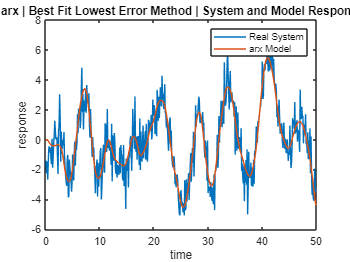

%%
figure(1)
plot(t,y_val,t,BestFit_y_hat)
legend('Real System','arx Model')
title(" arx | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

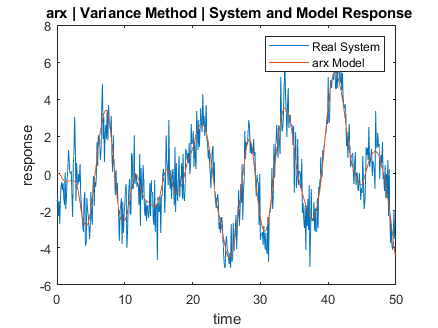


figure(2)
plot(t,y_val,t,Var_y_hat)
legend('Real System','arx Model')
title(" arx | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

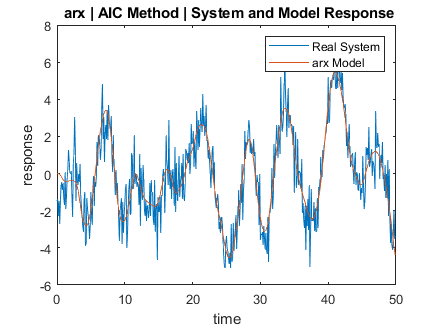


figure(3)
plot(t,y_val,t,AIC_y_hat)
legend('Real System','arx Model')
title(" arx | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

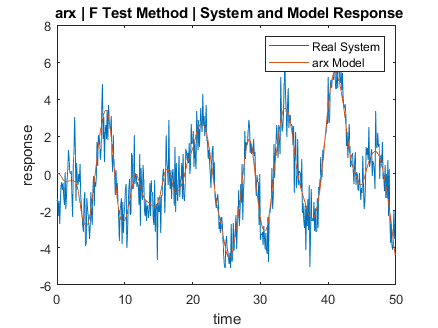


figure(4)
plot(t,y_val,t,FTest_y_hat)
legend('Real System','arx Model')
title(" arx | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

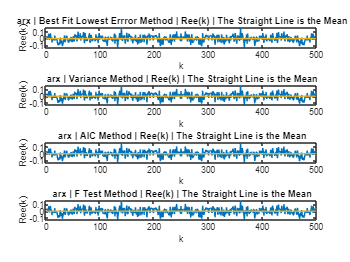

%%

figure(5)
subplot(4,1,1)
plot(1:N-1,arx_BestFit_Ree(2:end), 1:N-1, mean(arx_BestFit_Ree(2:end))*ones(length(1:N-1)))
title(" arx | Best Fit Lowest Errror Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,2)
plot(1:N-1,arx_Var_Ree(2:end), 1:N-1, mean(arx_Var_Ree(2:end))*ones(length(1:N-1)))
title(" arx | Variance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,3)
plot(1:N-1,arx_AIC_Ree(2:end), 1:N-1, mean(arx_AIC_Ree(2:end))*ones(length(1:N-1)))
title(" arx | AIC Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,4)
plot(1:N-1,arx_FTest_Ree(2:end), 1:N-1, mean(arx_FTest_Ree(2:end))*ones(length(1:N-1)))
title(" arx | F Test Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

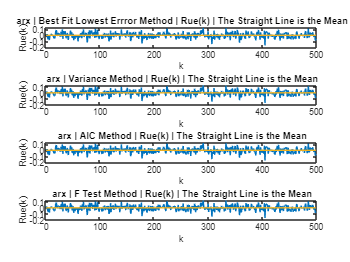

%%

figure(6)
subplot(4,1,1)
plot(1:N-1,arx_BestFit_Rue(2:end), 1:N-1, mean(arx_BestFit_Rue(2:end))*ones(length(1:N-1)))
title(" arx | Best Fit Lowest Errror Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,2)
plot(1:N-1,arx_Var_Rue(2:end), 1:N-1, mean(arx_Var_Rue(2:end))*ones(length(1:N-1)))
title(" arx | Variance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,3)
plot(1:N-1,arx_AIC_Rue(2:end), 1:N-1, mean(arx_AIC_Rue(2:end))*ones(length(1:N-1)))
title(" arx | AIC Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,4)
plot(1:N-1,arx_FTest_Rue(2:end), 1:N-1, mean(arx_FTest_Rue(2:end))*ones(length(1:N-1)))
title(" arx | F Test Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

%% 

figure(7)

denom = arx_AICModel(1:minAICIndex);
num = arx_AICModel(minAICIndex+1:minAICIndex*2);
G = tf(num', [1 denom'], 'Ts', Ts);
G_AIC_poles = pole(G);

fprintf(">>> We have used  u, y and v for model estimation under arx structure. \n")

>>> We have used  u, y and v for model estimation under arx structure. 


fprintf("    Accordingly, the transfer function of the proper system degree is as follows:\n")

    Accordingly, the transfer function of the proper system degree is as follows:


fprintf(" G(z) = \n")

 G(z) = 


disp(G)

  tf with properties:

       Numerator: {[0 0.0016 0.0062 0.0015]}
     Denominator: {[1 -2.8369 2.6900 -0.8521]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0.1000
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



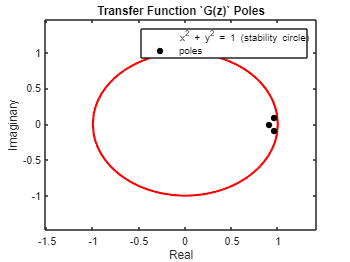


xx = -1:0.01:+1;
yy = [sqrt(1-xx.^2), flip(-sqrt(1-xx.^2))];
xx = [xx flip(xx)];


plot(xx, yy, LineWidth=2, Color="red")
hold on
scatter(real(G_AIC_poles), imag(G_AIC_poles), 'fill', 'black')
legend("x^2 + y^2 = 1 (stability circle)", "poles")
title("Transfer Function `G(z)` Poles")
xlabel("Real")
ylabel("Imaginary")



fprintf(">>> It is shown in the figure that all the poles are in the stability circle area and \n")

>>> It is shown in the figure that all the poles are in the stability circle area and 


fprintf("    hence, they are all stable. Therefre the estimated model in stable. \n")

    hence, they are all stable. Therefre the estimated model in stable. 
